Calculations of forces on fins for subsonic flight (Ma < 0.8):

- lift and drag forces due to AoA

- perpendicular forces due to rolling moment due to inherit misalignment of fins

system of coordinates (aligned with Ansys) for calculations:

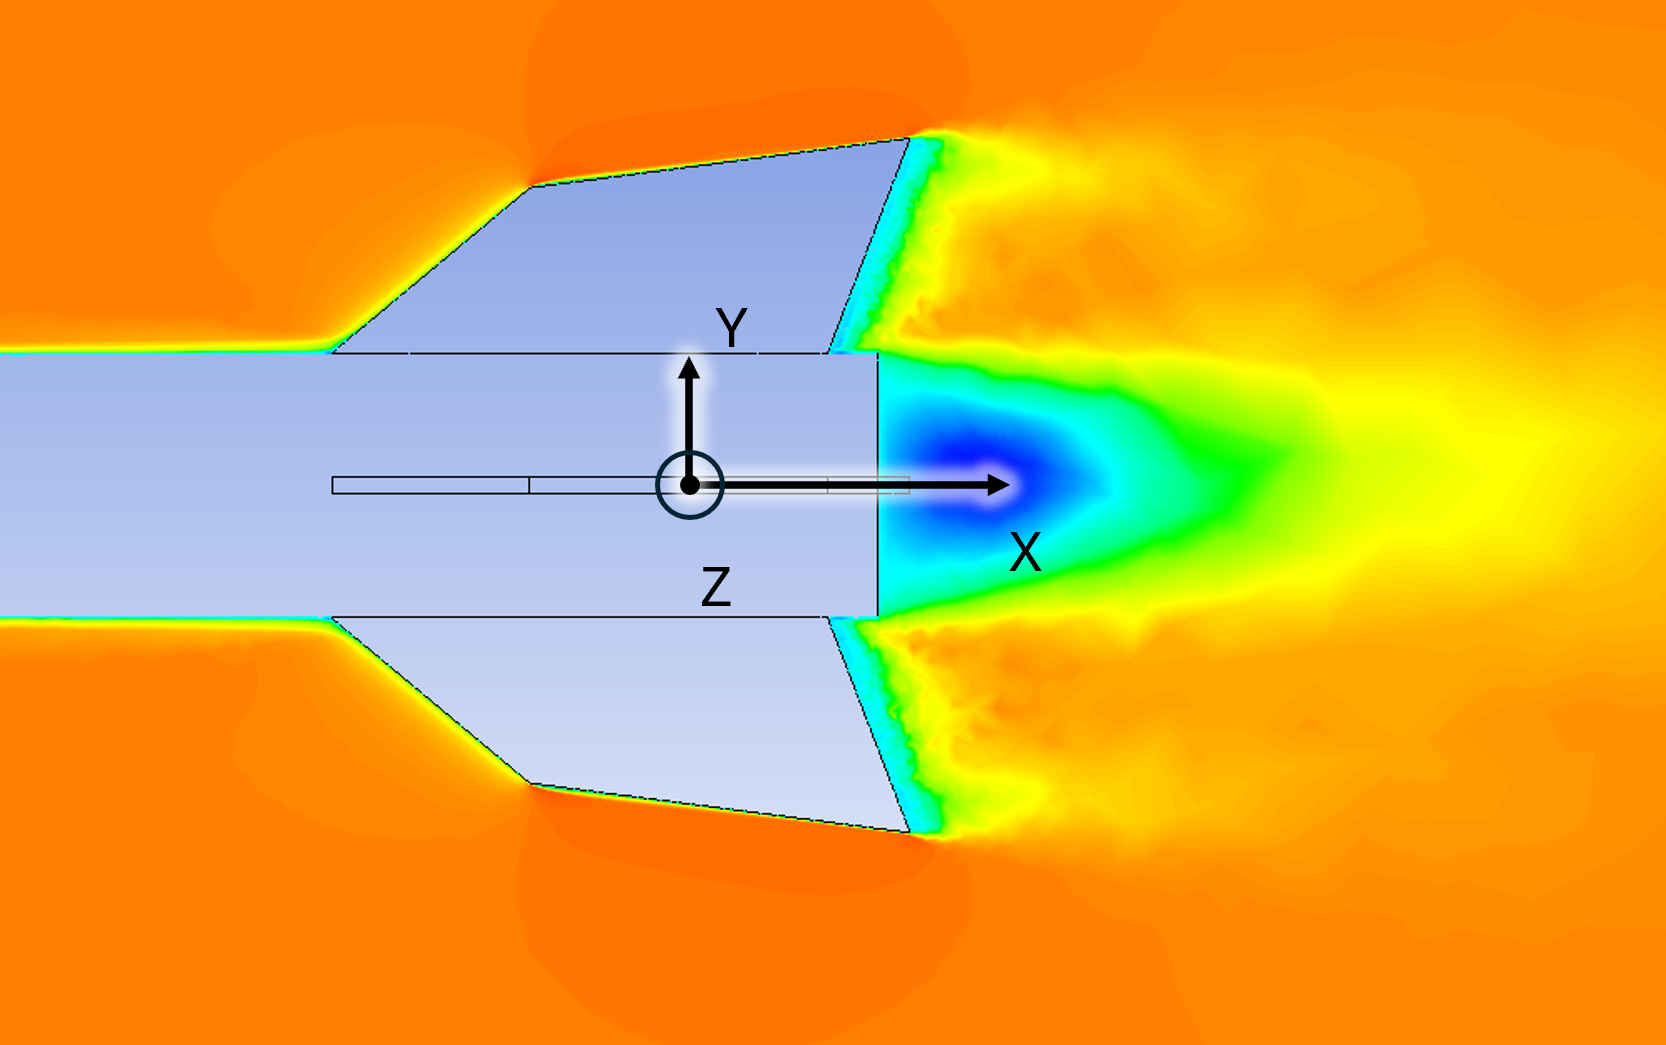

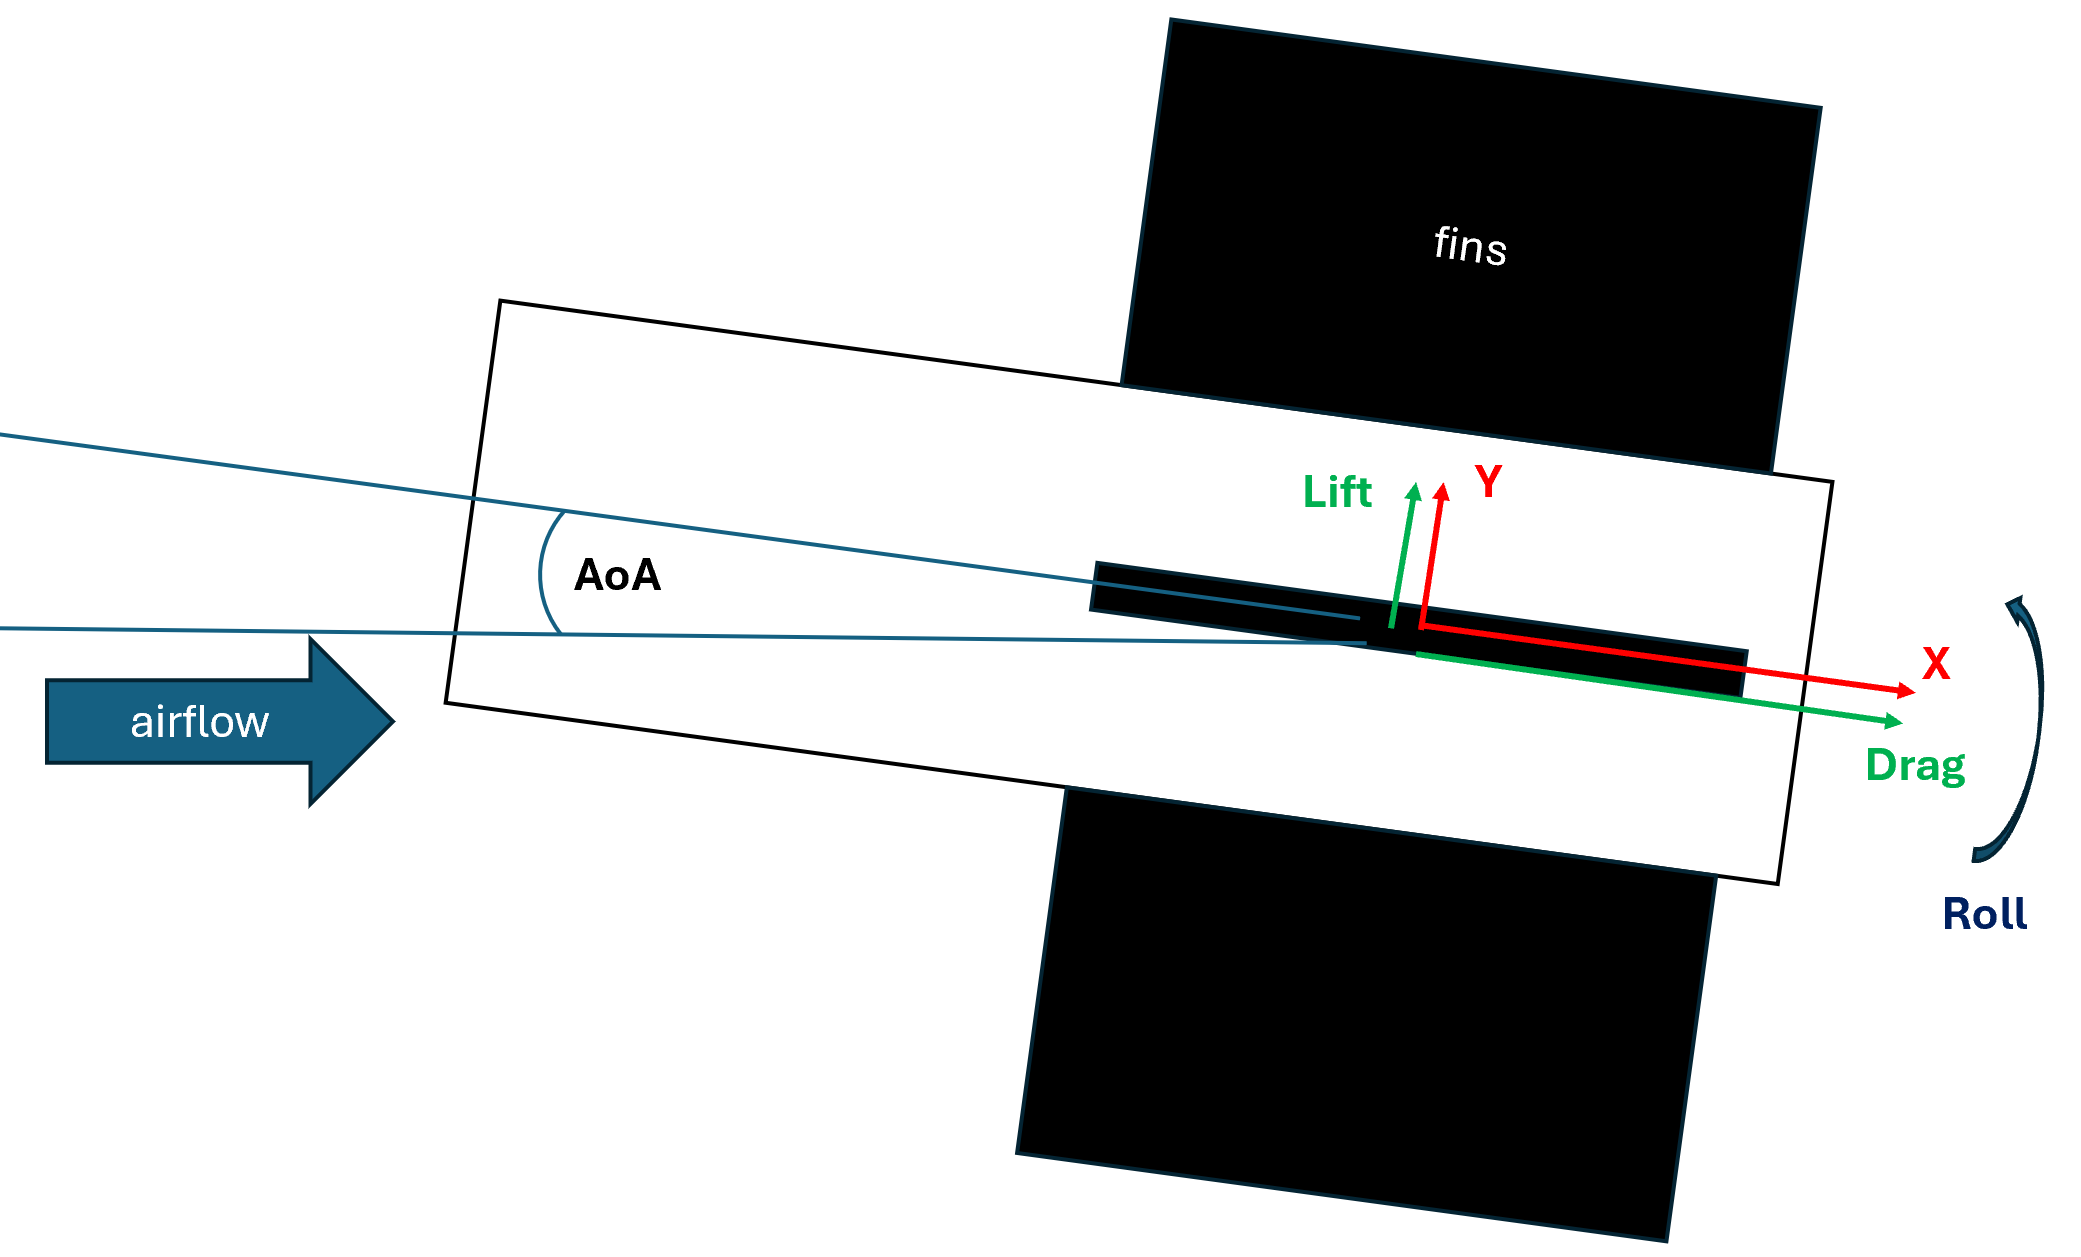

[a,b]=plate_2D_lift_drag(2)

a = 0.2193

b = 0.1994

[c,d]=lift_drag_sweep_correction(a,b,45)

c = 0.1096

d = 0.0705

# **Air Density Helper Function:**

function rho = air_density_calc(h)
    %h ... altitude over sealevel in [meters]
    %rho ... standard air pressure in [bar] calculated at given height

    rho=((288.15-0.0065*h)/288.25)^5.25588; %from 978-981-19-4585-4 (formula 2.63)
end

# **Roll Induced Force:**

%foo

# **Lift and Drag for 2D Angled Plate:**

Assumptions:

- small AoA < 12 deg (http://brennen.caltech.edu/fluidbook/externalflows/lift/flatplateairfoil.pdf)

- **=> attached laminar flow (!)**

- no drag from surface area (https://aviation.stackexchange.com/questions/21391/what-is-the-performance-of-a-flat-plate-wing)

- thin trailing edge (https://aviation.stackexchange.com/questions/21391/what-is-the-performance-of-a-flat-plate-wing)

            **=> kind of alligns* with Ansys at 2 degree (where no detaching occurs)**

*            *Ansys is double, but I have also found formulas with L=4*pi*rho*sin(alpha)*v^2 (FMII Skript)*

function [C_L, C_D]=plate_2D_lift_drag(AoA) %h, S, v)
    % Parameters:
    % h ... altitude above sea level in [meters]
    % AoA ... angle of attack in [degrees]
    % S ... single fin area in [m^2]
    % v ... air speed in [m/s]
    %
    % Outputs:
    % F_L ... lift force in Newton

    %rho = air_density_calc(h); %air density at given height in [bar]
    
    C_L = 2*pi*sin(AoA*pi/180); %from http://brennen.caltech.edu/fluidbook/externalflows/lift/flatplateairfoil.pdf
    % F_L = 0.5*rho*v^2*S*C_L; %Lift force in [N] from e.g. https://www1.grc.nasa.gov/beginners-guide-to-aeronautics/lift-coefficient/
    
    C_Di = C_L*sin(AoA); % from https://aviation.stackexchange.com/questions/21391/what-is-the-performance-of-a-flat-plate-wing
    C_Dp = 0; %due to assumptions 2 and 3 
    C_D = C_Di+C_Dp;
    % F_D = 0.5*rho*v^2*S*C_D; %Drag froce in [N] from e.g. https://stengel.mycpanel.princeton.edu/MAE331Lecture5.pdf
    % 
    % %align with coordinates
    % Fx = F_D;
    % Fy = F_L;
    % Fz = 0;

end

# **Lift and Drag for 3D, Swept Airfoil:**

Corrections from 2D:

- finite aspect ratio (AR) (AR < 3 => low-aspect ratio wing (according to 978-981-19-4585-4 p. 633))

- => vortex lift around the tip (for low-AR wings at AoA > 4 deg (according to 978-981-19-4585-4 p. 634))

- sweep

- (Skin friction in longitudenal direction (z-Axis) the fins have the most mounting support => not a critical force that will lead to destruction)

Assumptions:

- no sognificant airfoil shape

- delta wing shape

- no significant impact of downwash effects at trailing edge

- no rocket body intereference

            **=> investigation not usefull unless attached flow can be guaranteed** (see "Lift and Drag for 2D Angled Plate")

function [C_L, C_D] = vortex_3D_plate_lift_drag(AoA, AR)
    % Parameters:
    % h ... altitude above sea level in meters
    % AoA ... angle of attack in degrees
    % S ... single fin area
    % rho (h) ... air density (height) in mbar
    % v ... air speed in m/s

    % S ... wing area in [m^2]
    % AR ... aspect ratio
    % xi ... sweep angle in [deg]
    
    %--vortex lift through leading-edge-suction-analogy--
    %!!! "The vortex lift is the method by which highly swept wings (like delta wings) produce lift at high angles of attack +60deg." => hardly applies here!     
    if AR > 4
        %printf("(!!) aspect-ratio outside of non-linear NASA study https://ntrs.nasa.gov/api/citations/19670003842/downloads/19670003842.pdf")
        fprintf("(!!) aspect-ratio outside of source 978-981-19-4585-4 (formula 9.130) for Kv and Kp")
    end

    %K_v = 0.0775*AR+3.14; %linearization of Kv for delta wings with 0<AR<4 from https://ntrs.nasa.gov/api/citations/19670003842/downloads/19670003842.pdf 
    K_v = 3.0941+0.1181*AR-0.0069*AR^2; % vortex coefficient from 978-981-19-4585-4 (formula 9.130)
    K_p = -0.8223-0.0612*AR+2.2142*sqrt(AR); % from 978-981-19-4585-4 (formula 9.130)

    C_Lp = K_p*sin(AoA*pi/180)*cos(AoA*pi/180)^2; %lift coefficient determined by linearized potential-flow theory from 978-981-19-4585-4 (formula 9.123)
    C_Lv = K_v*cos(AoA*pi/180)*sin(AoA*pi/180)^2; %lift coefficient associated with leading- edge separation vortex from 978-981-19-4585-4 (formula 9.127)

    C_L = C_Lp+C_Lv;
    
    C_Di = K_p*cos(AoA*pi/180)*sin(AoA*pi/180)^2 + sin(AoA*pi/180)^3; %induced drag for detached vortex (worst case?) from 978-981-19-4585-4 (formula 9.129)
    
    C_D = C_Di; %???

    %F_L = 0.5*rho(h)*v^2*S*C_L; %from e.g. https://www1.grc.nasa.gov/beginners-guide-to-aeronautics/lift-coefficient/

    %--Finite Wing theory--
    http://aero-comlab.stanford.edu/aa200b/lect_notes/lect11.pdf
end

function [C_L, C_D] = lift_drag_sweep_correction(C_Ln, C_Dn, xi)
    % C_Ln ... Lift coefficent of non-swept (aka straight) wing
    % C_Ln ... Drag coefficient of non-swept (aka straight) wing
    % xi ... sweep in [deg]

    C_L = C_Ln*cos(xi*pi/180)^2; %from 978-981-19-4585-4 (formula 9.83)
    C_D = C_Dn*cos(xi*pi/180)^3; %from 978-981-19-4585-4 (formula 9.85)
end

# Points:

**subsonic sweep correction: Book chapter 11.144

# Questions:

- at what speed do we leave the rail? This low speed = low Re might risk stall of the fins = loss of control